clear;
m = 5;
l = 0.5;
J = eye(3, 3);
g = 9.81;

r0 = [100; 0; 0];
v0 = [0; 0; 0];
qi = angle2quat(0, pi/6, 0, 'ZYX')';
omega0 = [0; 0; 0];
x0 = [r0; v0; qi(2:end); omega0];

rf = [l; 0; 0];
vf = [-.1; 0; 0];
qf = angle2quat(0, 0, 0, 'ZYX')';
omegaf = [0; 0; 0];
xf = [rf; vf; qf(2:end); omegaf];

u0 = [0; 0; 0; 0];
uf = [0; 0; m*g; 0];

xmax = [.0001; 2; 2; .00005; 5; 5; .001; .001; .001; 1; 1; 1];
Q = diag(xmax.^-2);
umax = [pi/6; pi/6; 1500; 10];
R = diag(umax.^-2);

[A, B] = AB(xf, uf, m, J, l, g);

[K, S, P] = lqr(A, B, Q, R);

opts = odeset('RelTol',1e-12, 'AbsTol',1e-12);
tScale = linspace(0, 10, 10000);
[t, x] = ode45(@(t, x) get_deriv(t, x, K, m, J, l, g), tScale, x0, opts);
x = x';

for i = 1:size(x, 2)
    u(:, i) = -K*x(:, i);
    uref(:, i) = constrain(u(:, i));
    q1 = x(7, i);
    q2 = x(8, i);
    q3 = x(9, i);
    [yaw(i), pitch(i), roll(i)] = quat2angle([sqrt(1 - q1^2 - q2^2 - q3^2), q1, q2, q3], 'ZYX');
end

xref = [x(1:3, :); roll; pitch; yaw; x(4:6, :); x(10:12, :)];

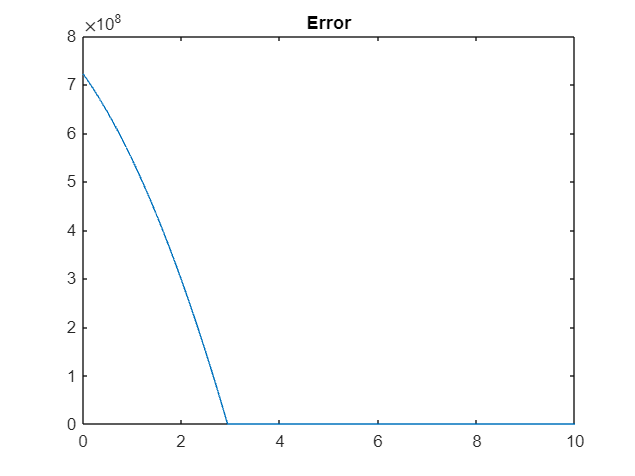

lin_error = zeros(1, size(x, 2));
for i = 1:size(x, 2)
    error = A*x(:, i) + B*u(:, i) - f(0, x(:, i), u(:, i), m, J, l, g);
    lin_error(i) = norm(error);
end

plot(t, lin_error);
title("Error");

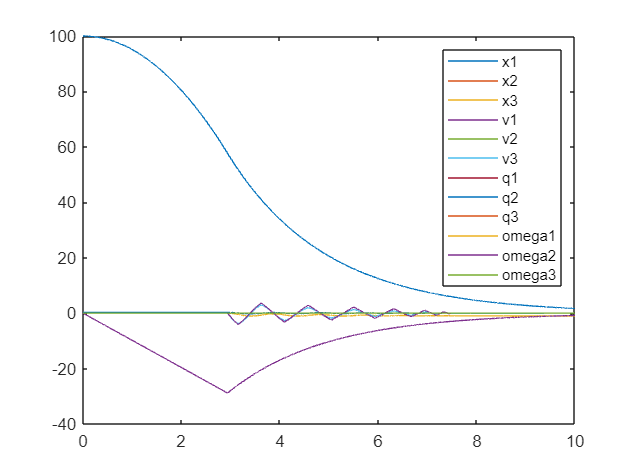

figure;
plot(t, x)
legend("x1", "x2", "x3", "v1", "v2", "v3", "q1", "q2", "q3", "omega1", "omega2", "omega3");

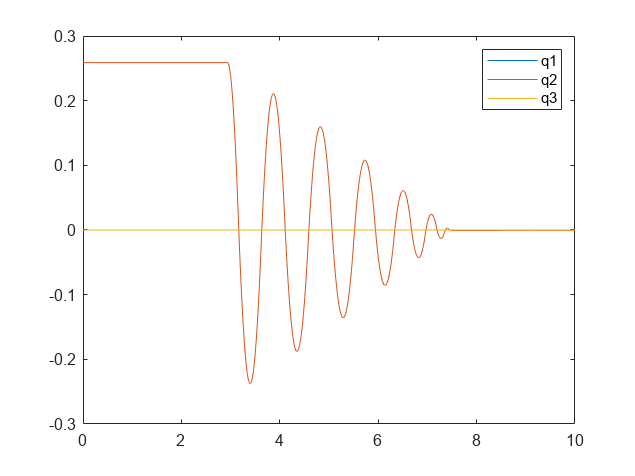


figure;
plot(t, x(7:9, :))
legend("q1", "q2", "q3");

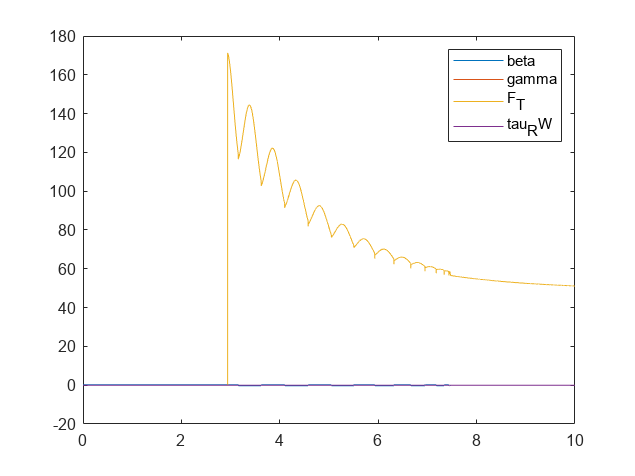


for i = 1:size(x, 2)
    u(:, i) = constrain(u(:, i));
end
figure
plot(t, u)
legend("beta", "gamma", "F_T", "tau_RW");


disp(x(1, end))

    1.6881



disp(max(u(2, :)))

   1.5263e-09



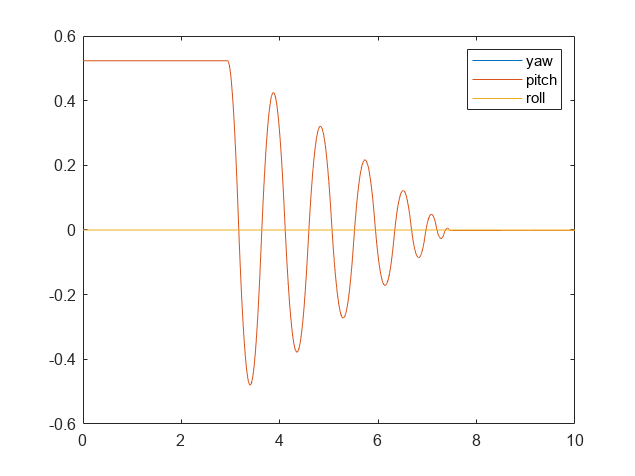


figure;
plot(t', [yaw; pitch; roll]);
legend("yaw", "pitch", "roll");

disp(pitch(end));

   -0.0011



function [A, B] = AB(x, u, m, J, l, g)
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    v1 = x(4);
    v2 = x(5);
    v3 = x(6);
    q1 = x(7);
    q2 = x(8);
    q3 = x(9);
    omega1 = x(10);
    omega2 = x(11);
    omega3 = x(12);

    betaAng = u(1);
    gammaAng = u(2);
    F_T = u(3);

    J1 = J(1);
    J2 = J(2);
    J3 = J(3);
    J4 = J(4);
    J5 = J(5);
    J6 = J(6);
    J7 = J(7);
    J8 = J(8);
    J9 = J(9);

    A = [0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0; 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0; 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0; 0, 0, 0, 0, 0, 0, -(F_T*sin(betaAng)*(2*conj(q3) - (2*conj(q1)*conj(q2))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) - F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q2) + (2*conj(q1)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, -(F_T*sin(betaAng)*(2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1)) - (2*(conj(q2))^2)/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) + 4*F_T*cos(betaAng)*cos(gammaAng)*conj(q2) - F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q1) + (2*conj(q2)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, -(F_T*sin(betaAng)*(2*conj(q1) - (2*conj(q2)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) + 4*F_T*cos(betaAng)*cos(gammaAng)*conj(q3) + F_T*cos(betaAng)*sin(gammaAng)*(2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1)) - (2*(conj(q3))^2)/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, 0, 0, 0; 0, 0, 0, 0, 0, 0, (F_T*sin(betaAng)*(2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1)) - (2*(conj(q1))^2)/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) - 4*F_T*cos(betaAng)*conj(q1)*sin(gammaAng) + F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q2) - (2*conj(q1)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, -(F_T*sin(betaAng)*(2*conj(q3) + (2*conj(q1)*conj(q2))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) - F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q1) - (2*conj(q2)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, -(F_T*sin(betaAng)*(2*conj(q2) + (2*conj(q1)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) + 4*F_T*cos(betaAng)*conj(q3)*sin(gammaAng) - F_T*cos(betaAng)*cos(gammaAng)*(2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1)) - (2*(conj(q3))^2)/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, 0, 0, 0; 0, 0, 0, 0, 0, 0, (4*F_T*conj(q1)*sin(betaAng) + F_T*cos(betaAng)*sin(gammaAng)*(2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1)) - (2*(conj(q1))^2)/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) + F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q3) + (2*conj(q1)*conj(q2))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, (4*F_T*conj(q2)*sin(betaAng) - F_T*cos(betaAng)*cos(gammaAng)*(2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1)) - (2*(conj(q2))^2)/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) + F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q3) - (2*conj(q1)*conj(q2))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, (F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q1) + (2*conj(q2)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))) + F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q2) - (2*conj(q1)*conj(q3))/conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))))/m, 0, 0, 0; 0, 0, 0, 0, 0, 0, -(omega1*q1)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), omega3/2 - (omega1*q2)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), - omega2/2 - (omega1*q3)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), sqrt(- q1^2 - q2^2 - q3^2 + 1)/2, -q3/2, q2/2; 0, 0, 0, 0, 0, 0, - omega3/2 - (omega2*q1)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), -(omega2*q2)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), omega1/2 - (omega2*q3)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), q3/2, sqrt(- q1^2 - q2^2 - q3^2 + 1)/2, -q1/2; 0, 0, 0, 0, 0, 0, omega2/2 - (omega3*q1)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), - omega1/2 - (omega3*q2)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), -(omega3*q3)/(2*sqrt(- q1^2 - q2^2 - q3^2 + 1)), -q2/2, q1/2, sqrt(- q1^2 - q2^2 - q3^2 + 1)/2; 0, 0, 0, 0, 0, 0, 0, 0, 0, (J3*J5^2*omega2 - J2*J6^2*omega3 + J3*J8^2*omega2 - J2*J9^2*omega3 + J1*J2*J6*omega2 - J1*J3*J5*omega2 - 2*J2*J4*J6*omega1 + 2*J3*J4*J5*omega1 + J1*J2*J9*omega3 - J1*J3*J8*omega3 - J2*J5*J6*omega2 + J3*J5*J6*omega3 - 2*J2*J7*J9*omega1 + 2*J3*J7*J8*omega1 - J2*J8*J9*omega2 + J4*J5*J9*omega3 - J4*J6*J8*omega3 + J3*J8*J9*omega3 - J5*J7*J9*omega2 + J6*J7*J8*omega2)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (omega3*J2^2*J9 + 2*J6*omega2*J2^2 - 2*omega2*J2*J3*J5 - omega3*J2*J3*J8 + J6*omega3*J2*J3 - J6*omega1*J2*J5 - omega1*J2*J8*J9 + J1*J6*omega1*J2 - omega3*J3^2*J5 + omega1*J3*J5^2 - J1*omega1*J3*J5 + omega1*J3*J8^2 + omega3*J5^2*J9 - 2*omega2*J5*J8*J9 - J6*omega3*J5*J8 - omega3*J5*J9^2 - J7*omega1*J5*J9 + 2*J6*omega2*J8^2 + J6*omega3*J8*J9 + J6*J7*omega1*J8)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), -(- omega2*J2^2*J9 - omega2*J2*J3*J6 - 2*omega3*J2*J3*J9 + J8*omega2*J2*J3 + omega1*J2*J6^2 + omega1*J2*J9^2 - J1*omega1*J2*J9 + omega2*J3^2*J5 + 2*J8*omega3*J3^2 - omega1*J3*J5*J6 - J8*omega1*J3*J9 + J1*J8*omega1*J3 - omega2*J5^2*J9 - 2*omega3*J5*J6*J9 + J8*omega2*J5*J6 + omega2*J5*J9^2 - J4*omega1*J5*J9 + 2*J8*omega3*J6^2 - J8*omega2*J6*J9 + J4*J8*omega1*J6)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7); 0, 0, 0, 0, 0, 0, 0, 0, 0, -(omega2*J1^2*J6 + omega3*J1^2*J9 - 2*omega1*J1*J4*J6 - J3*omega2*J1*J4 - omega3*J1*J6^2 - J5*omega2*J1*J6 - 2*omega1*J1*J7*J9 - J3*omega3*J1*J7 - omega3*J1*J9^2 - J8*omega2*J1*J9 + omega3*J4^2*J9 + 2*J3*omega1*J4^2 - omega3*J4*J6*J7 + J3*omega3*J4*J6 - omega2*J4*J7*J9 + J3*J5*omega2*J4 + omega2*J6*J7^2 + 2*J3*omega1*J7^2 + J3*omega3*J7*J9 + J3*J8*omega2*J7)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), -(J1^2*J6*omega1 - J3^2*J4*omega3 + J6*J7^2*omega1 - J4*J9^2*omega3 - J1*J3*J4*omega1 + 2*J1*J2*J6*omega2 - 2*J2*J3*J4*omega2 + J1*J3*J6*omega3 - J1*J5*J6*omega1 + J3*J4*J5*omega1 + J1*J2*J9*omega3 - J2*J3*J7*omega3 - J1*J8*J9*omega1 + J3*J7*J8*omega1 + J4*J5*J9*omega3 - J4*J7*J9*omega1 - J5*J6*J7*omega3 - 2*J4*J8*J9*omega2 + 2*J6*J7*J8*omega2 + J6*J7*J9*omega3)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (- omega1*J1^2*J9 - omega2*J1*J3*J6 - 2*omega3*J1*J3*J9 + J7*omega1*J1*J3 + omega1*J1*J6^2 + omega1*J1*J9^2 - J2*omega2*J1*J9 + omega2*J3^2*J4 + 2*J7*omega3*J3^2 - omega1*J3*J4*J6 - J7*omega1*J3*J9 + J2*J7*omega2*J3 - omega1*J4^2*J9 - 2*omega3*J4*J6*J9 + J7*omega1*J4*J6 + omega2*J4*J9^2 - J5*omega2*J4*J9 + 2*J7*omega3*J6^2 - J7*omega2*J6*J9 + J5*J7*omega2*J6)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7); 0, 0, 0, 0, 0, 0, 0, 0, 0, (omega2*J1^2*J5 + omega3*J1^2*J8 - 2*omega1*J1*J4*J5 - J2*omega2*J1*J4 - omega2*J1*J5^2 - J6*omega3*J1*J5 - 2*omega1*J1*J7*J8 - J2*omega3*J1*J7 - omega2*J1*J8^2 - J9*omega3*J1*J8 + omega3*J4^2*J8 + 2*J2*omega1*J4^2 - omega3*J4*J5*J7 + J2*omega2*J4*J5 - omega2*J4*J7*J8 + J2*J6*omega3*J4 + omega2*J5*J7^2 + 2*J2*omega1*J7^2 + J2*omega2*J7*J8 + J2*J9*omega3*J7)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), -(- omega1*J1^2*J5 - 2*omega2*J1*J2*J5 - omega3*J1*J2*J8 + J4*omega1*J1*J2 + omega1*J1*J5^2 - J3*omega3*J1*J5 + omega1*J1*J8^2 + omega3*J2^2*J7 + 2*J4*omega2*J2^2 - J4*omega1*J2*J5 - omega1*J2*J7*J8 + J3*J4*omega3*J2 + omega3*J5^2*J7 - omega1*J5*J7^2 - 2*omega2*J5*J7*J8 - J9*omega3*J5*J7 - J4*omega3*J5*J8 + J4*omega1*J7*J8 + 2*J4*omega2*J8^2 + J4*J9*omega3*J8)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (J1^2*J8*omega1 - J2^2*J7*omega2 + J4^2*J8*omega1 - J5^2*J7*omega2 - J1*J2*J7*omega1 + J1*J3*J5*omega2 - J2*J3*J4*omega2 + J1*J2*J8*omega2 - J1*J5*J6*omega1 + J2*J4*J6*omega1 + 2*J1*J3*J8*omega3 - 2*J2*J3*J7*omega3 - J4*J5*J7*omega1 - J1*J8*J9*omega1 + J2*J7*J9*omega1 + J4*J5*J8*omega2 + 2*J4*J6*J8*omega3 - 2*J5*J6*J7*omega3 - J4*J8*J9*omega2 + J5*J7*J9*omega2)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7)];
    B = [0, 0, 0, 0; 0, 0, 0, 0; 0, 0, 0, 0; -(F_T*cos(betaAng)*(2*conj(q1)*conj(q3) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q2)) + F_T*sin(betaAng)*sin(gammaAng)*(2*conj(q1)*conj(q2) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) - F_T*cos(gammaAng)*sin(betaAng)*(2*(conj(q2))^2 + 2*(conj(q3))^2 - 1))/m, (F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q1)*conj(q2) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) + F_T*cos(betaAng)*sin(gammaAng)*(2*(conj(q2))^2 + 2*(conj(q3))^2 - 1))/m, -(sin(betaAng)*(2*conj(q1)*conj(q3) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q2)) - cos(betaAng)*sin(gammaAng)*(2*conj(q1)*conj(q2) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) + cos(betaAng)*cos(gammaAng)*(2*(conj(q2))^2 + 2*(conj(q3))^2 - 1))/m, 0; -(F_T*cos(betaAng)*(2*conj(q2)*conj(q3) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q1)) + F_T*cos(gammaAng)*sin(betaAng)*(2*conj(q1)*conj(q2) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) - F_T*sin(betaAng)*sin(gammaAng)*(2*(conj(q1))^2 + 2*(conj(q3))^2 - 1))/m, -(F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q1)*conj(q2) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) + F_T*cos(betaAng)*cos(gammaAng)*(2*(conj(q1))^2 + 2*(conj(q3))^2 - 1))/m, -(sin(betaAng)*(2*conj(q2)*conj(q3) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q1)) - cos(betaAng)*cos(gammaAng)*(2*conj(q1)*conj(q2) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) + cos(betaAng)*sin(gammaAng)*(2*(conj(q1))^2 + 2*(conj(q3))^2 - 1))/m, 0; -(F_T*cos(gammaAng)*sin(betaAng)*(2*conj(q1)*conj(q3) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q2)) - F_T*cos(betaAng)*(2*(conj(q1))^2 + 2*(conj(q2))^2 - 1) + F_T*sin(betaAng)*sin(gammaAng)*(2*conj(q2)*conj(q3) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q1)))/m, (F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q2)*conj(q3) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q1)) - F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q1)*conj(q3) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q2)))/m, (sin(betaAng)*(2*(conj(q1))^2 + 2*(conj(q2))^2 - 1) + cos(betaAng)*cos(gammaAng)*(2*conj(q1)*conj(q3) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q2)) + cos(betaAng)*sin(gammaAng)*(2*conj(q2)*conj(q3) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q1)))/m, 0; 0, 0, 0, 0; 0, 0, 0, 0; 0, 0, 0, 0; (F_T*J2*J9*l*cos(betaAng) - F_T*J3*J8*l*cos(betaAng) + F_T*J2*J6*l*sin(betaAng)*sin(gammaAng) - F_T*J3*J5*l*sin(betaAng)*sin(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), -(F_T*J2*J6*l*cos(betaAng)*cos(gammaAng) - F_T*J3*J5*l*cos(betaAng)*cos(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (J2*J9*l*sin(betaAng) - J3*J8*l*sin(betaAng) - J2*J6*l*cos(betaAng)*sin(gammaAng) + J3*J5*l*cos(betaAng)*sin(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (J5*J9 - J6*J8)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7); -(F_T*J1*J9*l*cos(betaAng) - F_T*J3*J7*l*cos(betaAng) + F_T*J1*J6*l*sin(betaAng)*sin(gammaAng) - F_T*J3*J4*l*sin(betaAng)*sin(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (F_T*J1*J6*l*cos(betaAng)*cos(gammaAng) - F_T*J3*J4*l*cos(betaAng)*cos(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), -(J1*J9*l*sin(betaAng) - J3*J7*l*sin(betaAng) - J1*J6*l*cos(betaAng)*sin(gammaAng) + J3*J4*l*cos(betaAng)*sin(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), -(J4*J9 - J6*J7)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7); (F_T*J1*J8*l*cos(betaAng) - F_T*J2*J7*l*cos(betaAng) + F_T*J1*J5*l*sin(betaAng)*sin(gammaAng) - F_T*J2*J4*l*sin(betaAng)*sin(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), -(F_T*J1*J5*l*cos(betaAng)*cos(gammaAng) - F_T*J2*J4*l*cos(betaAng)*cos(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (J1*J8*l*sin(betaAng) - J2*J7*l*sin(betaAng) - J1*J5*l*cos(betaAng)*sin(gammaAng) + J2*J4*l*cos(betaAng)*sin(gammaAng))/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7), (J4*J8 - J5*J7)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7)];
end

% function [xref, uref] = ode_traj(x0, ts, xcrits, ucrits, timeScale)
%     
% end

function xdot = get_deriv(t, x, K, m, J, l, g)
    u = -K*x;
    u = constrain(u);
    xdot = f(t, x, u, m, J, l, g);
end

function u_new = constrain(u)
    angleLimit = pi/12;
    thrustLimit = 400;
    tauLimit = 10;
    
    beta = u(1);
    gamma = u(2);
    F_T = u(3);
    tau_RW = u(4);

    if beta > angleLimit
        beta = angleLimit;
    elseif beta < -angleLimit
        beta = -angleLimit;
    end
    if gamma > angleLimit
        gamma = angleLimit;
    elseif gamma < -angleLimit
        gamma = -angleLimit;
    end
    if F_T > thrustLimit
        F_T = thrustLimit;
    elseif F_T < 0
        F_T = 0;
    end
    if tau_RW > tauLimit
        tau_RW = tauLimit;
    elseif tau_RW < -tauLimit
        tau_RW = -tauLimit;
    end

    u_new = [beta; gamma; F_T; tau_RW];
end

function Ks = critical_gains(xs, us, Q, R, m, J, l, g)
    Ks = zeros(size(us, 1), size(xs, 1), size(xs, 3));
    for i = 1:length(xs)
        [Ak, Bk] = AB(xs(:, :, i), us(:, :, i), m, J, l, g);
        [Ks(:, :, i), ~, ~] = lqr(Ak, Bk, Q, R);
    end
end

function xdot = f(t, x, u, m, J, l, g)
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    v1 = x(4);
    v2 = x(5);
    v3 = x(6);
    q1 = x(7);
    q2 = x(8);
    q3 = x(9);
    omega1 = x(10);
    omega2 = x(11);
    omega3 = x(12);

    betaAng = u(1);
    gammaAng = u(2);
    F_T = u(3);
    tau_RW = u(4);

    J1 = J(1);
    J2 = J(2);
    J3 = J(3);
    J4 = J(4);
    J5 = J(5);
    J6 = J(6);
    J7 = J(7);
    J8 = J(8);
    J9 = J(9);

    xdot = [v1; v2; v3; -(g*m + F_T*sin(betaAng)*(2*conj(q1)*conj(q3) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q2)) - F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q1)*conj(q2) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) + F_T*cos(betaAng)*cos(gammaAng)*(2*(conj(q2))^2 + 2*(conj(q3))^2 - 1))/m; -(F_T*sin(betaAng)*(2*conj(q2)*conj(q3) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q1)) - F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q1)*conj(q2) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q3)) + F_T*cos(betaAng)*sin(gammaAng)*(2*(conj(q1))^2 + 2*(conj(q3))^2 - 1))/m; (F_T*sin(betaAng)*(2*(conj(q1))^2 + 2*(conj(q2))^2 - 1) + F_T*cos(betaAng)*cos(gammaAng)*(2*conj(q1)*conj(q3) - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q2)) + F_T*cos(betaAng)*sin(gammaAng)*(2*conj(q2)*conj(q3) + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*conj(q1)))/m; (omega1*sqrt(- q1^2 - q2^2 - q3^2 + 1))/2 - (omega2*q3)/2 + (omega3*q2)/2; (omega2*sqrt(- q1^2 - q2^2 - q3^2 + 1))/2 + (omega1*q3)/2 - (omega3*q1)/2; (omega3*sqrt(- q1^2 - q2^2 - q3^2 + 1))/2 - (omega1*q2)/2 + (omega2*q1)/2; (J2^2*J6*omega2^2 + J2^2*J9*omega2*omega3 - J2*J3*J5*omega2^2 + J2*J3*J6*omega2*omega3 - J2*J3*J8*omega2*omega3 + J2*J3*J9*omega3^2 - J2*J5*J6*omega1*omega2 - J2*J6^2*omega1*omega3 - J4*J2*J6*omega1^2 + J1*J2*J6*omega1*omega2 - F_T*l*cos(betaAng)*sin(gammaAng)*J2*J6 - J2*J8*J9*omega1*omega2 - J2*J9^2*omega1*omega3 - J7*J2*J9*omega1^2 + J1*J2*J9*omega1*omega3 + F_T*l*sin(betaAng)*J2*J9 - J3^2*J5*omega2*omega3 - J3^2*J8*omega3^2 + J3*J5^2*omega1*omega2 + J3*J5*J6*omega1*omega3 + J4*J3*J5*omega1^2 - J1*J3*J5*omega1*omega2 + F_T*l*cos(betaAng)*sin(gammaAng)*J3*J5 + J3*J8^2*omega1*omega2 + J3*J8*J9*omega1*omega3 + J7*J3*J8*omega1^2 - J1*J3*J8*omega1*omega3 - F_T*l*sin(betaAng)*J3*J8 + J5^2*J9*omega2*omega3 - J5*J6*J8*omega2*omega3 + J5*J6*J9*omega3^2 - J5*J8*J9*omega2^2 - J5*J9^2*omega2*omega3 - J7*J5*J9*omega1*omega2 + J4*J5*J9*omega1*omega3 + tau_RW*J5*J9 - J6^2*J8*omega3^2 + J6*J8^2*omega2^2 + J6*J8*J9*omega2*omega3 + J7*J6*J8*omega1*omega2 - J4*J6*J8*omega1*omega3 - tau_RW*J6*J8)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7); -(J1^2*J6*omega1*omega2 + J1^2*J9*omega1*omega3 - J1*J3*J4*omega1*omega2 + J1*J3*J6*omega2*omega3 - J1*J3*J7*omega1*omega3 + J1*J3*J9*omega3^2 - J1*J4*J6*omega1^2 - J1*J6^2*omega1*omega3 - J5*J1*J6*omega1*omega2 + J2*J1*J6*omega2^2 - F_T*l*cos(betaAng)*sin(gammaAng)*J1*J6 - J1*J7*J9*omega1^2 - J1*J9^2*omega1*omega3 - J8*J1*J9*omega1*omega2 + J2*J1*J9*omega2*omega3 + F_T*l*sin(betaAng)*J1*J9 - J3^2*J4*omega2*omega3 - J3^2*J7*omega3^2 + J3*J4^2*omega1^2 + J3*J4*J6*omega1*omega3 + J5*J3*J4*omega1*omega2 - J2*J3*J4*omega2^2 + F_T*l*cos(betaAng)*sin(gammaAng)*J3*J4 + J3*J7^2*omega1^2 + J3*J7*J9*omega1*omega3 + J8*J3*J7*omega1*omega2 - J2*J3*J7*omega2*omega3 - F_T*l*sin(betaAng)*J3*J7 + J4^2*J9*omega1*omega3 - J4*J6*J7*omega1*omega3 + J4*J6*J9*omega3^2 - J4*J7*J9*omega1*omega2 - J4*J9^2*omega2*omega3 - J8*J4*J9*omega2^2 + J5*J4*J9*omega2*omega3 + tau_RW*J4*J9 - J6^2*J7*omega3^2 + J6*J7^2*omega1*omega2 + J6*J7*J9*omega2*omega3 + J8*J6*J7*omega2^2 - J5*J6*J7*omega2*omega3 - tau_RW*J6*J7)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7); (J1^2*J5*omega1*omega2 + J1^2*J8*omega1*omega3 - J1*J2*J4*omega1*omega2 + J1*J2*J5*omega2^2 - J1*J2*J7*omega1*omega3 + J1*J2*J8*omega2*omega3 - J1*J4*J5*omega1^2 - J1*J5^2*omega1*omega2 - J6*J1*J5*omega1*omega3 + J3*J1*J5*omega2*omega3 - F_T*l*cos(betaAng)*sin(gammaAng)*J1*J5 - J1*J7*J8*omega1^2 - J1*J8^2*omega1*omega2 - J9*J1*J8*omega1*omega3 + J3*J1*J8*omega3^2 + F_T*l*sin(betaAng)*J1*J8 - J2^2*J4*omega2^2 - J2^2*J7*omega2*omega3 + J2*J4^2*omega1^2 + J2*J4*J5*omega1*omega2 + J6*J2*J4*omega1*omega3 - J3*J2*J4*omega2*omega3 + F_T*l*cos(betaAng)*sin(gammaAng)*J2*J4 + J2*J7^2*omega1^2 + J2*J7*J8*omega1*omega2 + J9*J2*J7*omega1*omega3 - J3*J2*J7*omega3^2 - F_T*l*sin(betaAng)*J2*J7 + J4^2*J8*omega1*omega3 - J4*J5*J7*omega1*omega3 + J4*J5*J8*omega2*omega3 - J4*J7*J8*omega1*omega2 - J4*J8^2*omega2^2 - J9*J4*J8*omega2*omega3 + J6*J4*J8*omega3^2 + tau_RW*J4*J8 - J5^2*J7*omega2*omega3 + J5*J7^2*omega1*omega2 + J5*J7*J8*omega2^2 + J9*J5*J7*omega2*omega3 - J6*J5*J7*omega3^2 - tau_RW*J5*J7)/(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7)];
end